clear variables; close all;clc
% unscented kalman filter example 2
% tracking of an airplane
% states = (distance, velocity, altitude) = (x, xdot, y)
% measures = (range, bearing) = (slant, elevation angle) = (r, etha)

addpath('../utilities');

% time step [s]
dt = 3;

% 1 minute of measures
endtime = 360;

% number of measures
n = endtime/dt+1;

% std of the two sensors
slant_range_std = 500;
elevation_angle_std = deg2rad(0.5);

% aircraft information
ac_pos = [0, 1000];
ac_vel = [100, 0];
ac_vel_std = 0.02;

% radar information
r_pos = [0, 0];

% dimensions
dim_x = 4;
dim_z = 2;

% initial condition
% mean
x = [0, 90, 1100, 0]';
% covariance
P = diag([300^2, 30^2, 150^2, 3^2]);

% process noise covariance
Q(1:2,1:2) = [0.25*dt^4 0.5*dt^3;0.5*dt^3 dt^2]*0.1;
Q(3:4,3:4) = [0.25*dt^4 0.5*dt^3;0.5*dt^3 dt^2]*0.1;

% measure noise covariance
R = diag([slant_range_std^2 elevation_angle_std^2]);
  
% (non linear) state transition function
f = @(x, dt) f_cv_radar(x, dt);

% (non linear) measurement function
h = @(x) h_radar(x);

% sigma points deterministic sampling
alpha = 0.1;
beta = 2;
kappa = -1;

% data structures
x_posterior = zeros(dim_x,n);
x_prior = zeros(dim_x,n);
zs = zeros(dim_z,n);
xs = zeros(dim_x-2,n);

[Wm, Wc] = merwe_weights(alpha, beta, kappa, dim_x);

% filtering
for ii=1:n
    % simulate change in altitude over time (velocity)
    % to comment/uncomment to compare with example 2
    if ii == 20
        ac_vel(2) = 5;
    end
    
    % simulate new aircraft position (x, y)
    ac_pos = aircraft_simulator(ac_pos, ac_vel, ac_vel_std, dt);
    xs(:,ii) = ac_pos;
    
    % simulate new radar measure (range; bearing)
    z = radar_simulator(r_pos, slant_range_std, elevation_angle_std, ac_pos);
    zs(:,ii) = z;
    
% 0) deterministic sampling from given mean and covariance (mass points)
    sigmas = merwe_points(alpha, beta, kappa, dim_x, x, P);
    
% 1) predict:
    % (non linear) forward transition of the mass points (prediction)
    sigmas_f = f(sigmas, dt);
    % unscented transformation (computed mean and covariance of the mass
    % forwarded points)
    [x, P] = unscented_transform(sigmas_f, Wm, Wc, Q);
    x_prior(:,ii) = x;
    
% 2) update (correct)
    % (non linear) measurement space transformation of the mass forwarded points
    sigmas_h = h(sigmas_f);
    % unscented transformation (computed mean and covariance of the mass
    % forwarded points)
    [zp, Pz] = unscented_transform(sigmas_h, Wm, Wc, R);
    % cross covariance
    Pxz = (sigmas_f-x) * diag(Wc) * (sigmas_h-zp)';
    % kalman gain
    K = Pxz/(Pz);
    % residual
    y = z - zp;
    % posterior mean
    x = x + K*y;
    % posterior covariance
    P = P - K*Pz*K';
    x_posterior(:,ii) = x;
end

% plots

% to comment/uncomment to compare with example 4:
% using the doppler sensor the std of the forward velocity drops significantly
std(x_posterior(2,10:end))

ans = 2.2057

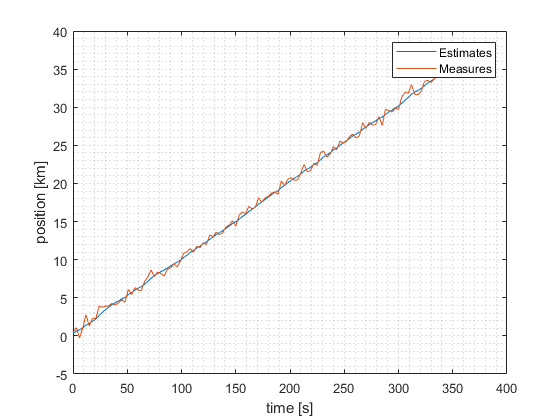


% 1 minute of measures
time = 0:dt:endtime;

figure
plot(time,x_posterior(1,:)*1e-3);
hold on;
plot(time,zs(1,:)*1e-3);
grid minor;
xlabel('time [s]');
ylabel('position [km]')
legend('Estimates','Measures');

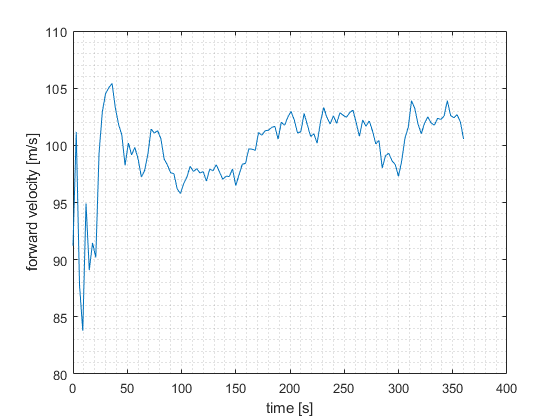

figure
plot(time,x_posterior(2,:));
grid minor;
xlabel('time [s]');
ylabel('forward velocity [m/s]')

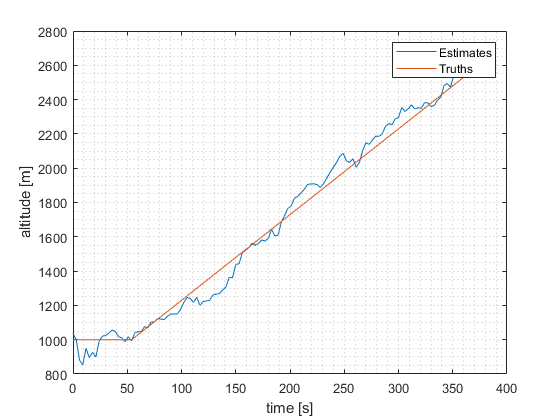

figure
plot(time,x_posterior(3,:));
hold on; grid minor;
plot(time,xs(2,:));
legend('Estimates','Truths')
xlabel('time [s]');
ylabel('altitude [m]')